clear, close all, clc

Et batteri med 3 forskellige typer testes ved 3 forskellige temperaturer.

load('dataset_problem_14_3.mat')
n = 4

n = 4

Opgave a)

Test standardhypoteserne (B, A og interaktion) med alpha = 0.01.

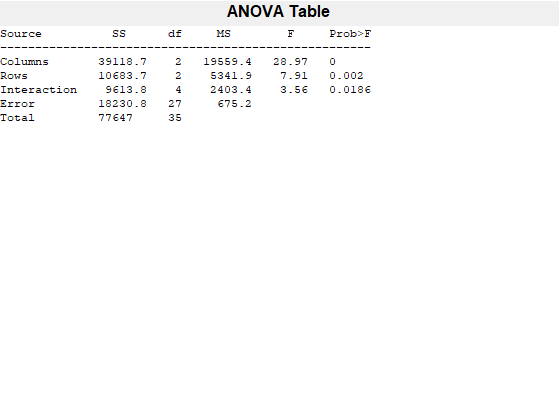

P =     0.0000    0.0020    0.0186


M = data(:,3:6);
M = M';
M = [M(:,1:3);M(:,4:6);M(:,7:9)];

P = anova2(M,n)


% Det ses her, at vi forkaster hypoteserne om A og B,
% men ikke om interaktion. Både type og temperatur
% påvirker altså batteriet.

Opgave b)

Analyser interaktionen grafisk

[R,VR,CM] = ANOVA2Residuals(M,n)

R =    -4.7500  -23.2500  -37.5000
   20.2500  -17.2500   12.5000
  -60.7500   22.7500   24.5000
   45.2500   17.7500    0.5000
   -5.7500   16.2500  -24.5000
   32.2500    2.2500   20.5000
    3.2500  -13.7500    8.5000
  -29.7500   -4.7500   -4.5000
   -6.0000   28.2500   10.5000
  -34.0000  -25.7500   18.5000


VR =    -4.7500  -23.2500  -37.5000   20.2500  -17.2500   12.5000  -60.7500   22.7500   24.5000   45.2500   17.7500    0.5000   -5.7500   16.2500  -24.5000   32.2500    2.2500   20.5000    3.2500  -13.7500    8.5000  -29.7500   -4.7500   -4.5000   -6.0000   28.2500   10.5000  -34.0000  -25.7500   18.5000   24.0000    4.2500   -3.5000   16.0000   -6.7500  -25.5000


CM =   134.7500   57.2500   57.5000
  155.7500  119.7500   49.5000
  144.0000  145.7500   85.5000


% TWO-FACTOR INTERACTION PLOT

Opgave c)

Analyser residualerne fra eksperimentet.

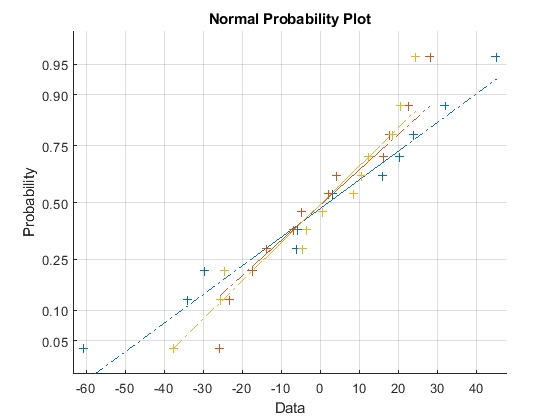

figure(4)
normplot(R)

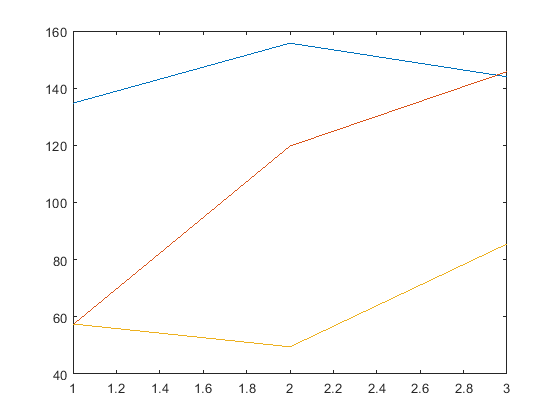

plot(CM)